
% Defining DH parameters
L1 = Link('d', 0.352, 'a', 0.070, 'alpha', pi/2);
L2 = Link('d', 0.070, 'a', 0.360, 'alpha', 0);
L3 = Link('d', 0.070, 'a', 0.445, 'alpha', 0);

% setting mass for each link
L1.m = 50

 
L1 = 
Revolute(std): theta=q, d=0.352, a=0.07, alpha=1.5708, offset=0


L2.m = 30

 
L2 = 
Revolute(std): theta=q, d=0.07, a=0.36, alpha=0, offset=0


L3.m = 20

 
L3 = 
Revolute(std): theta=q, d=0.07, a=0.445, alpha=0, offset=0



% Create the robot model
irb140 = SerialLink([L1 L2 L3], 'name', 'IRB140');

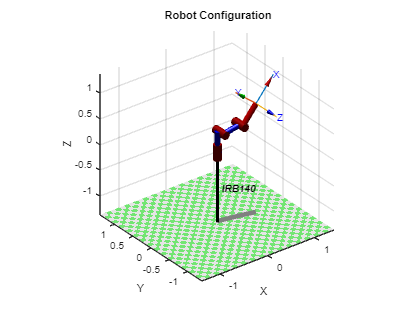



% Define the gear ratio
gear_ratio = 100;  % Gear ratio of 1:100 for each motor

% Joint configuration
q = deg2rad([0, 10, 40]);

% Plot the robot configuration to visualize it
irb140.plot(q);
title('Robot Configuration');


% torques at each joint
torques = irb140.gravload(q);

% total torque at the motor
motor_torques = torques / gear_ratio;


disp('Joint torques required to overcome gravity (in Nm):');

Joint torques required to overcome gravity (in Nm):


disp(torques);

    0.0000  230.0185   56.1211




disp('Motor torques required to overcome gravity with gear ratio 1:100 (in Nm):');

Motor torques required to overcome gravity with gear ratio 1:100 (in Nm):


disp(motor_torques);

    0.0000    2.3002    0.5612



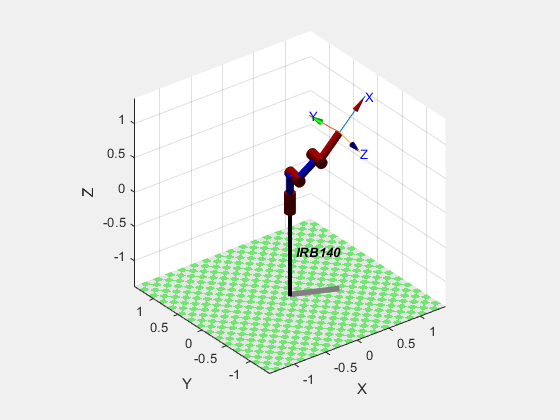

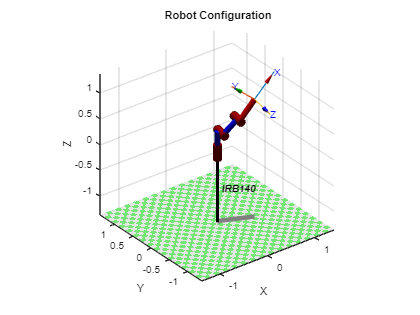

% Start and end configurations
q_start = deg2rad([10, 20, 30]);
q_end = deg2rad([-10, 40, 10]);


% Generate the joint-space trajectory with zero velocity at start and stop
[q_traj, qd_traj, qdd_traj] = jtraj(q_start, q_end, 10);

% Visualize the trajectory
figure;
set(gcf,'visible','on');
irb140.plot(q_traj);

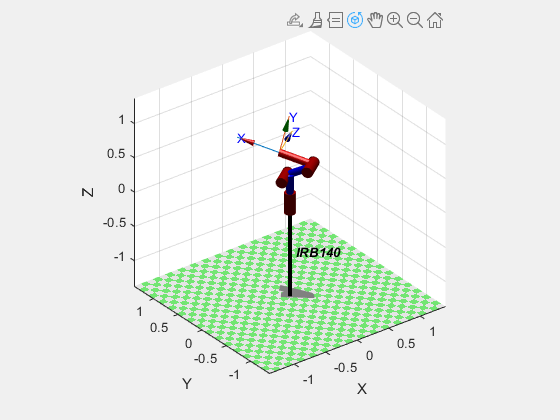

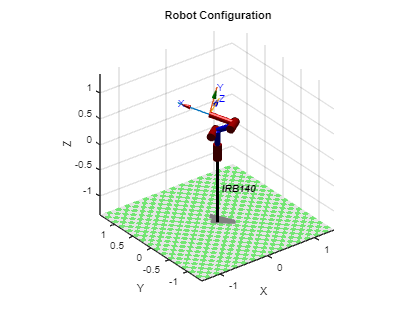

% setting gravity in the negative z direction
irb140.gravity = [0; 0; -9.81];

% setting initial conditions for free fall.
q0 = [0, 0, 0];     % Initial joint positions
qd0 = [0, 0, 0];    % Initial joint velocities

% setting time span for the simulation
t_end = 5;
timestep = 0.05; 
t = 0:timestep:t_end;

% run forward dynamics simulation with zero torques using an anonymous function
[t, q_traj] = irb140.fdyn(t_end, @(robot, t, q, qd) [0; 0; 0], q0, qd0);

% Animation loop to visualize the free-fall motion
figure;
set(gcf,'visible','on');
for i = 1:length(t)
    irb140.plot(q_traj(i, :), 'delay', timestep);
end